clear all

allResults = sensiAna_YJM_xPxR(0.1,1);

allResults.maxSocial

ans = struct with fields:
     prop_R0: [0.0869 0.5946 0.9320]
    alpha_P0: [0.6599 0.5946 0.5425]
    alpha_P1: [0.9640 0.5946 0.2258]
    alpha_R0: [0.6355 0.5946 0.5528]
     omega_R: [0.6645 0.5946 0.5577]
     omega_P: [0.2669 0.5946 0.9212]
       Omega: [0.5987 0.5946 0.5899]
        Td_c: [0.4161 0.5946 0.8946]
         k_P: [0.7336 0.5946 0.4707]
         k_R: [0.5774 0.5946 0.6119]
         c_R: [0.5344 0.5946 0.6753]
         c_P: [0.9343 0.5946 0.2737]
       kappa: [0.0975 0.5946 1.0000]
       delta: [0.3088 0.5946 0.9225]
          s_: [0.7154 0.5946 0.5177]
       C_at0: [0.6340 0.5946 0.5563]
       C_oc0: [0.6008 0.5946 0.5892]
      C_veg0: [0.7099 0.5946 0.4845]
       C_so0: [0.5255 0.5946 0.6658]
         k_p: [0.9421 0.5946 0.2932]
         k_c: [0.5853 0.5946 0.6041]
         k_M: [0.4437 0.5946 0.7484]
         k_r: [0.2674 0.5946 0.9474]
         E_a: [0.9177 0.5946 0.3112]
        k_sr: [0.2163 0.5946 0.9745]
         k_t: [0.7922 0.5946 0.4233]
           c

res_ = allResults;
resNames = fieldnames(allResults.maxSocial);

give2barh = [];
fldnames  = fieldnames(res_.maxSocial);
for i =1:length(fldnames  )
    fldname_ = fldnames{i};
    give2barh = [give2barh; res_.maxSocial.(fldname_)];
end

ctst = categorical(fldnames)'

ctst = 1×38 categorical array
     prop_R0      alpha_P0      alpha_P1      alpha_R0      omega_R      omega_P      Omega      Td_c      k_P      k_R      c_R      c_P      kappa      delta      s_      C_at0      C_oc0      C_veg0      C_so0      k_p      k_c      k_M      k_r      E_a      k_sr      k_t      c      A      S      tao_CH4      P_0      F_0      chi      zeta      f_max      omega      T_c      t_f 


% sort A in descending order (decreasing A values) 
% and keep the sort index in "sortIdx"
%[A,sortIdx] = sort(std(give2barh'),'descend');
%sizeBar = abs((give2barh(:,1))' - (give2barh(:,2))') + abs((give2barh(:,2))' - (give2barh(:,3))');
max_temp = max(give2barh, [],2);
min_temp = min(give2barh, [],2);
sizeBar = abs((max_temp)' - (give2barh(:,2))' + (give2barh(:,2))' - (min_temp)');
[A,sortIdx] = sort(sizeBar,'ascend');

% sort B using the sorting index
B = give2barh(sortIdx,:);
sortedNames = categorical(resNames(sortIdx))';
%sortedNames = reordercats(sortedNamesNice, fliplr(namesNice));
mn1 = mean(give2barh);
mn1 = mn1(2); 

resNames

resNames = 38×1 cell array
    {'prop_R0' }
    {'alpha_P0'}
    {'alpha_P1'}
    {'alpha_R0'}
    {'omega_R' }
    {'omega_P' }
    {'Omega'   }
    {'Td_c'    }
    {'k_P'     }
    {'k_R'     }
    {'c_R'     }
    {'c_P'     }
    {'kappa'   }
    {'delta'   }
    {'s_'      }
    {'C_at0'   }
    {'C_oc0'   }
    {'C_veg0'  }
    {'C_so0'   }
    {'k_p'     }
    {'k_c'     }
    {'k_M'     }
    {'k_r'     }
    {'E_a'     }
    {'k_sr'    }
    {'k_t'     }
    {'c'       }
    {'A'       }
    {'S'       }
    {'tao_CH4' }


resNames(7)

ans = 1×1 cell array
    {'Omega'}


resNames(34)

ans = 1×1 cell array
    {'zeta'}


disp(apple)

Unrecognized function or variable 'apple'.

temp_str = resNames(1); % cell
if strcmp(temp_str{1}, 'prop_R0')
    resNames(1) = {'\rho_R'};
    resNames(2) = {'\alpha_{P0}'};
    resNames(3) = {'\alpha_{P1}'};
    resNames(4) = {'\alpha_{R0}'};
    resNames(5) = {'\omega_R'};
    resNames(6) = {'\omega_P'};
    resNames(7) = {'\Omega'};
    temp_str2 = resNames(13);
    if strcmp(temp_str2{1}, 'kappa')
        incr = 1+2;
        resNames(13) ={'\kappa'};
    else
        incr = 0;
    end    
    
    resNames(11+incr) = {'\delta'};
    resNames(13+incr) = {'C_{at0}'};
    resNames(14+incr) = {'C_{oc0}'};
    resNames(15+incr) = {'C_{veg0}'};
    resNames(16+incr) = {'C_{so0}'};
    resNames(22+incr) = {'k_{sr}'};
    resNames(27+incr) = {'\tau_{CH4}'};
    resNames(30+incr) = {'\chi'};
    resNames(31+incr) = {'\zeta'};
    resNames(32+incr) = {'f_{max}'};
    resNames(33+incr) = {'\omega'};
end

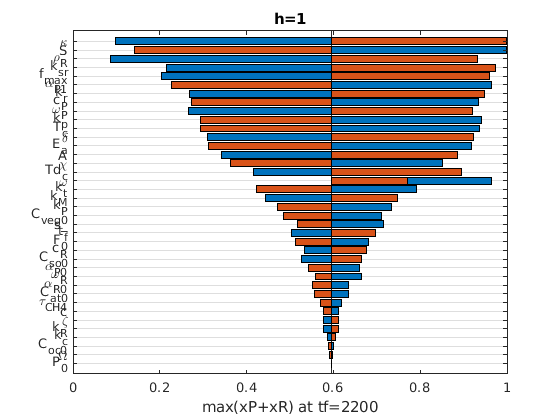

clf
barh(give2barh(sortIdx,1), 'stacked', 'BaseValue', mn1)
hold on
barh(give2barh(sortIdx,3),'stacked', 'BaseValue', mn1)
len__ = length(sortIdx);
yticks(1:len__)
set(gca, "YTickLabel", resNames(sortIdx))
title('h=1')
xlabel("max(xP+xR) at tf=2200")
ax=gca;ax.YGrid='on';